%% Problem 2
clear all

clc

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




Gp = 40/(s^2 + 3*s + 4.5);
Kp = 40/4.5;
Gs = 1;
Ga = -0.09;
Gr = 1;

Da0 = 8.5e-3;
Dp0 = 3e-3;
as = 0.01;
ws = 50;

%1)
Kd = 1;
Gf = 1/(Kd*Gs);

%2) 
R0 = 1;
er = 0.35;
nu = 1;
Kc_2 = abs(Kd^2*R0/(Kp*er*Ga));

%3)
eda = 1.75e-2;
%no further contrains! controller already type one

%4)
edp = 1e-3;
Kc_4 = abs(Dp0/(Kp*edp*Gs*Ga*Gf));

Kc = max(Kc_2,Kc_4);

%5)
eds = 2e-4;
M_T_HF = eds*Gs/as;
%wc <= 3.5

%6-8)

over = 0.08;
zeta = abs(log(over)/sqrt(pi^2 + (log(over))^2));
Tp0 = (1/(2*zeta*sqrt(1-zeta^2)));
Sp0 = (2*zeta*sqrt(2+4*zeta^2 + 2*sqrt(1+8*zeta^2))/(sqrt(1+8*zeta^2) + 4*zeta^2-1));

tr = 2.5;
ts = 10;
alpha = 0.05;

wn_1 = (pi - acos(zeta))/(tr*sqrt(1-zeta^2));
wn_2 = -log(alpha)/(ts*zeta);

wc_1 = wn_1*sqrt(sqrt(1+4*zeta^4)-2*zeta^2);
wc_2 = wn_2*sqrt(sqrt(1+4*zeta^4)-2*zeta^2);

wc = max(wc_1,wc_2);

%%%%%%
%Kc >= 3.75
Kc = -4;

%0.81 < wc < 3.5

wcd = 2; 

Rd_1 = zpk((1 + s/1.38)/(1 + s/22.07));
Rd_2 = zpk((1 + s/2.11)/(1 + s/33.68));
Ri = zpk((1 + s/0.06)/(1 + s/0.02));
% Gc = Kc/s*Rd_1*Rd_2*Ri;
Gc=Kc/s

Gc =
 
  -4
  --
  s
 
Continuous-time transfer function.





L = zpk(Gp*Gc*Ga*Gs*Gf)

L =
 
         14.4
  ------------------
  s (s^2 + 3s + 4.5)
 
Continuous-time zero/pole/gain model.



zpk(L)

ans =
 
         14.4
  ------------------
  s (s^2 + 3s + 4.5)
 
Continuous-time zero/pole/gain model.



p =    0.0000 + 0.0000i
  -1.5000 + 1.5000i
  -1.5000 - 1.5000i


P = 0

P = number of Open loop poles in rhp


N = -1

N =  number of anti-clockwise encirclements


Z = 1

Z = number of closed loop poles in rhp


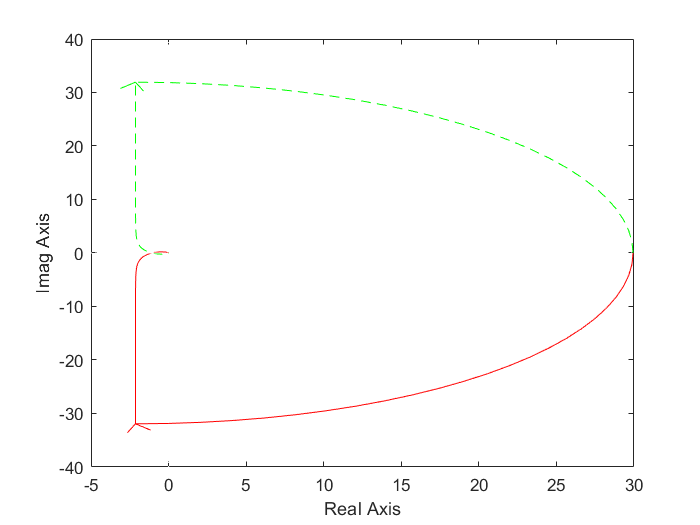




nyquist1([14.4],[1 3 4.5 0])

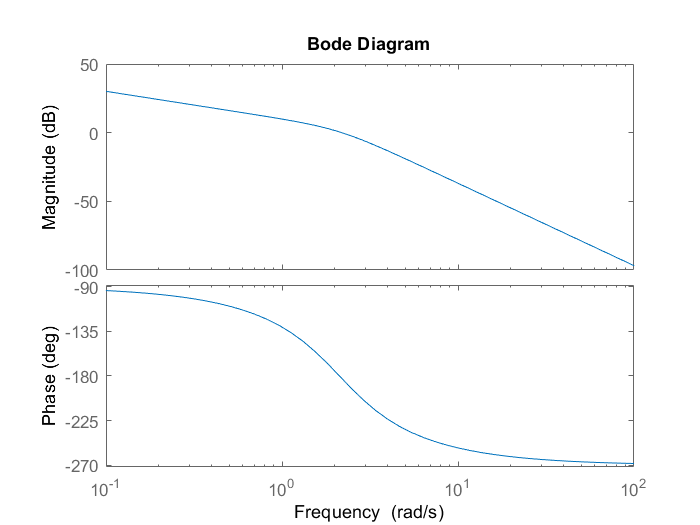

H = Gf*Gs;
Gry = 1/H*L/(1+L);

figure(1)
bode(L)


figure(2)
myngridst(Tp0,Sp0)
hold on
nichols(L)

figure(3)
time = 0:0.01:100

time =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


[y,t]=step(Gry,time);
plot(t,y)
grid on

%with this solution I get respect every requirement, but I'm quite close to
%the constant magnitute loci.







